# Linear classification

Using the simplest model/hypothesis for machine learning is the $h(x)=w_{weight}.x + b_{bias}$, on this case your parameters $w_{height}$ will store a pattern to every class that you need to classify, $b_{bias}$ is a independend term that has the job to push the model/hypothesis prediction towards some class independently of the input, kind of a prejudice.

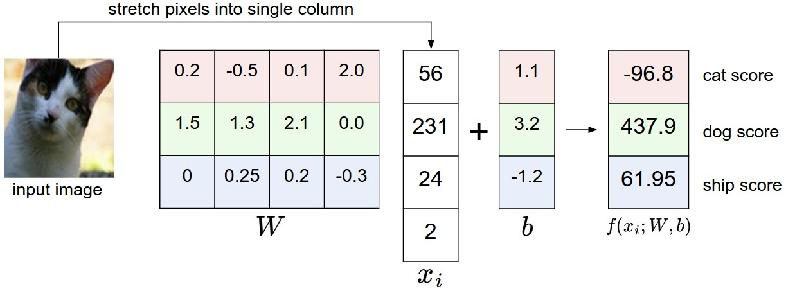

x = [56 231 24 2]';
W = [0.2 -0.5 0.1 2.0; 1.5 1.3 2.1 0.0; 0 0.25 0.2 -0.3];
b = [1.1 3.2 -1.2]';
scores = (W*x + b);
disp(scores);

  -96.8000
  437.9000
   60.7500



## Merging bias

In order to force the whole operation to be a matrix multiplication you can merge the bias with the weight matrix

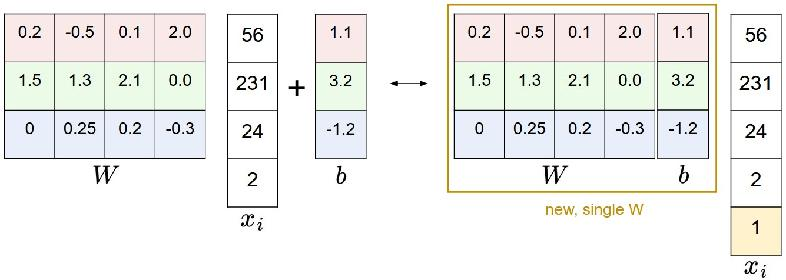

x_new = [x; 1];
W_merged = [W,b];
scores = W_merged * x_new;
disp(scores);

  -96.8000
  437.9000
   60.7500



## Loss Function

The loss function will be used to give us a metric on how good the current set of weights $[w_{weight},b_{bias}]$ are. The choice of loss function depend on the type of job. For instance for classification we should use the Softmax/SVM loss function and for regression we should use the mean square error.


$$L =  \underbrace{ \frac{1}{N} \sum_i L_i }_\text{data loss} + \underbrace{ \lambda R(W) }_\text{regularization loss}$$


## Softmax/SVM loss

As mentioned use these loss function for multi-class classification problems


$$L_{softmax} = -\log\left(\frac{e^{labels}}{ \sum_j e^{scores} }\right)$$



$$L_{SVM} = \sum_{j\neq y_i} \max(0, s_j - s_{y_i} + \Delta)$$


## Example

scores = [-2.85 0.86 0.28];
correct_label_idx = 3;

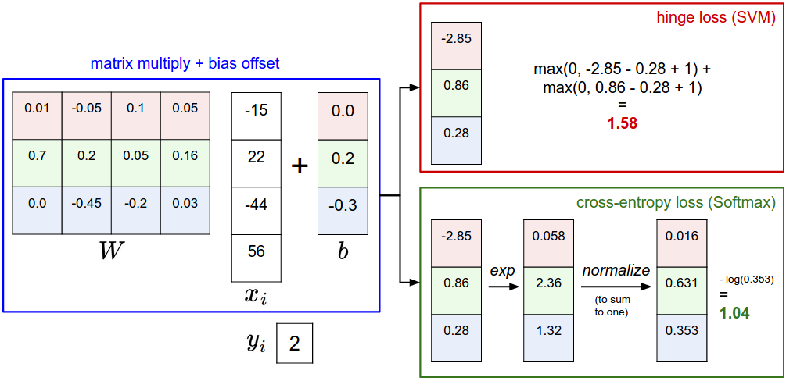

## Implementing Softmax

Actually we don't implement the softmax directly from the formula we do some changes to make it more numerically stable.

% Fix numerical instability
new_scores = scores - max(scores);
sum_prob = sum(exp(new_scores));
probabilities = exp(new_scores) ./ sum_prob;    
Li = -log(probabilities(correct_label_idx));
disp(Li);

    1.0402



## Implementing SVM

delta = 1;
% Calculate the margin for everything including the correct classes
margins = max(0,scores - scores(correct_label_idx) + delta);
% Only consider margin on max wrong class
margins(correct_label_idx) = 0;
Li = sum(margins);
disp(Li);

    1.5800

